% This is an example of an isetauto scene
%
% It has object instances
%

ieInit;
if ~piDockerExists, piDockerConfig; end

chdir(piRootPath);
addpath(genpath(pwd));

## This rendering seems to match on dev and dev-resources

fileName = fullfile(piRootPath, 'data/scenes/low-poly-taxi/low-poly-taxi.pbrt');
thisR = piRead(fileName);

Read 12 materials and 0 textures.
ObjectBegin processing.
Identified 1 assets; parsed up to line 10
Identified 1 assets; parsed up to line 129
Identified 1 assets; parsed up to line 77


thisR.set('skymap',fullfile(piRootPath,'data/skymaps','sky-rainbow.exr'));

Using skymap:  /Users/wandell/Documents/MATLAB/iset3d-v4/data/skymaps/sky-rainbow.exr



piWrite(thisR);
thisR.show('objects');


----- Summary of recipe: recipe

                      index       material           positions (m)              sizes (m)       
                      _____    _______________    ____________________    ______________________

    Plane_O             4      {'Material'   }    {'0.00 0.00 0.00'  }    {'165.41 165.41 0.00'}
    car-body.002_O      8      {'Bumper'     }    {'0.50 1.34 0.78'  }    {'0.12 0.05 0.04'    }
    car-body.003_O     11      {'Black'      }    {'0.01 1.39 0.68'  }    {'0.09 0.08 0.07'    }
    Cube_O             14      {'taxi_head'  }    {'-0.02 -0.26 1.29'}    {'0.22 0.08 0.13'    }
    Cube.001_O         17      {'Bumper'     }    {'-0.00 1.22 0.54' }    {'1.45 0.37 0.26'    }
    Cube.001_1_O       19      {'Black'      }  

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/low-poly-taxi/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/low-poly-taxi/ ...
Done (0.60 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell13537 sh -c "cd /iset/iset3d-v4/local/low-poly-taxi && rm -rf renderings/{*,.*}  &&  cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps  && pbrt --gpu --outfile renderings/low-poly-taxi.exr low-poly-taxi.pbrt "
Rendered remotely in: 10.73 sec
Pull: rsync -r  wandell@m

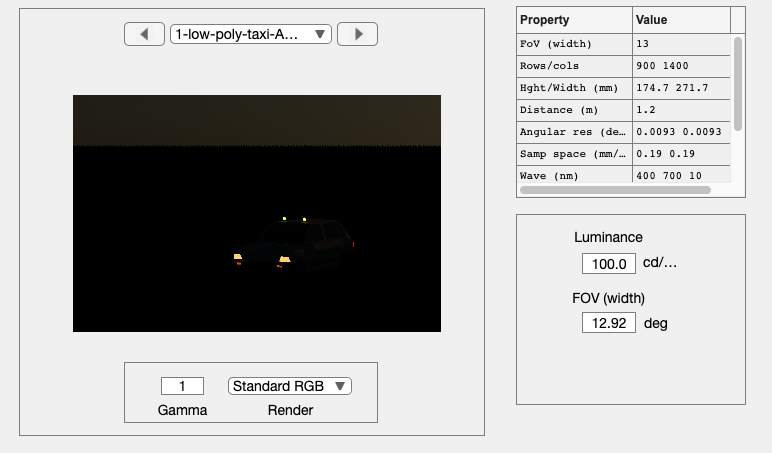


scene = piWRS(thisR);

ip = piRadiance2RGB(scene,'etime',1/30);

eT: 33.333333 ms 


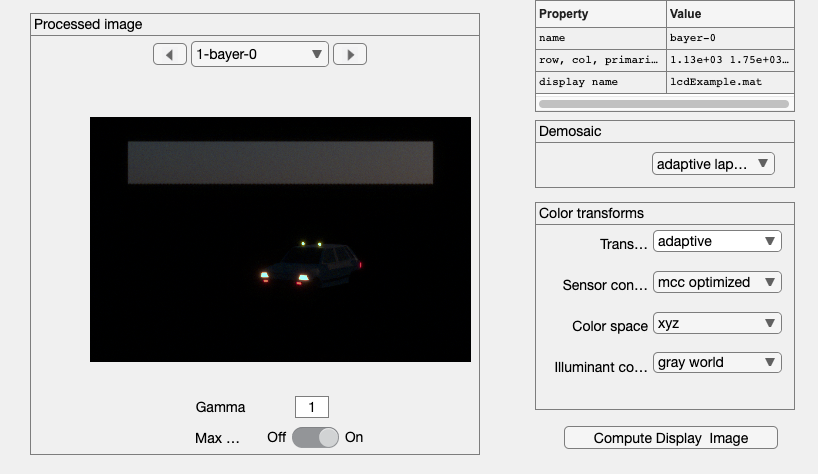

ipWindow(ip);

ipSet(ip,'gamma',0.5);

## Add a second car

carName = 'taxi';

rotationMatrix = piRotationMatrix('z', -15);
position       = [-4 0 0];

thisR   = piObjectInstanceCreate(thisR, [carName,'_m_B'], ...
    'rotation',rotationMatrix, 'position',position);
thisR.assets = thisR.assets.uniqueNames;

scene = piWRS(thisR);

ip = piRadiance2RGB(scene,'etime',1/30);

ipWindow(ip);